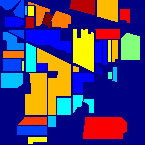

clear;
clc;

addpath('D:\Matlab\Data');
addpath('D:\Matlab\SSCCE');

HSI_gt = importdata('Data\Indian_pines_gt.mat');
L =  importdata('D:\Matlab\SSCCE\results\parameter\spatial81_m500.mat');

gt = HSI_gt(:);
imshow(HSI_gt, [], 'Border', 'tight');
colormap('jet');

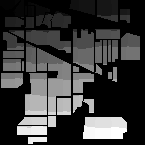

% impixelinfo;

[m, n] = size(HSI_gt);
L = reshape(L, [m, n]);

L(L == -1) = 0;

% tmp = 101;
% L(L == tmp) = 1000;
% L(L == 0) = tmp;
% L(L == 1000) = 0;

% add = zeros(3, 86);
% L = [L;add];

imshow(L, [], 'Border', 'tight');

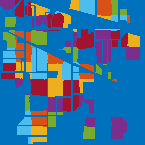

imshow(L, [], 'Border', 'tight', 'initialmagnification', 'fit');
colormap('lines');

% impixelinfo;

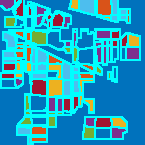

% figure;
BW = boundarymask(L);
color_map = gray2color(L, lines);

imshow(imoverlay(color_map, BW, 'cyan'), [], 'Border', 'tight');

imshow(imoverlay(color_map, BW, 'cyan'), 'InitialMagnification', 67, 'Border', 'tight', 'initialmagnification', 'fit');

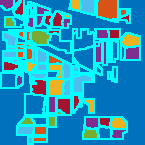

print('C:\Users\xdzha\Desktop\Figures\Section5\Robust\spatial_alpha500.svg', '-dsvg');

function color_map = gray2color(img, map)
%将灰度图像转换为彩色图像

img = round(img / max(max(img)) * 255) + 1;
sz = size(img);
color_map = zeros(sz(1), sz(2), 3);

for i = 1:sz(1)
    for j = 1:sz(2)
        idx = img(i,j);
        tmp = reshape(map(idx,:),1,1,3);
        color_map(i,j,:) = tmp;
    end
end
end